2.    Sum of Sinusoids Method

Generate g with different M

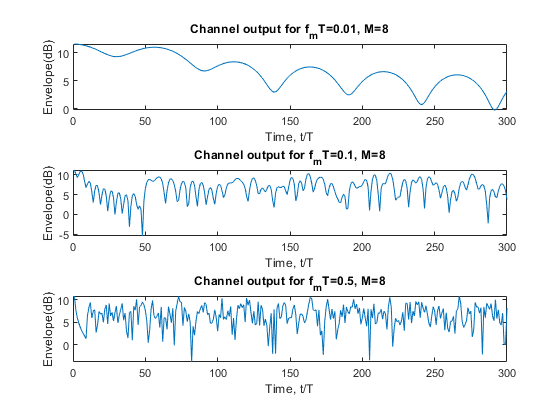

clear
M=[8,16];
f_mT=[0.01,0.1,0.5];
%Set T=1
T=1;
f_m=[0.01,0.1,0.5]/T;
for i=1:M(1)
    theta_1(i)=2*pi*i/(2*(2*M(1)+1));
    beta_1(i)=pi*i/M(1);
end
for i=1:M(2)
    theta_2(i)=2*pi*i/(2*(2*M(2)+1));
    beta_2(i)=pi*i/M(2);
end
%f_ij=f_m(i)*cos(theta_j)
f_11=f_m(1)*cos(theta_1);
f_12=f_m(1)*cos(theta_2);
f_21=f_m(2)*cos(theta_1);
f_22=f_m(2)*cos(theta_2);
f_31=f_m(3)*cos(theta_1);
f_32=f_m(3)*cos(theta_2);

%g_ij=2*sqrt(2)*[sum(cos(beta_j).*cos(2*pi*f_ij*t));sum(sin(beta_j).*cos(2*pi*f_ij*t))]
%sampling g_ij at time t=[1:samples]
samples=10^4;
for t=1:samples
    g_11(:,t)=2*sqrt(2)*[sum(cos(beta_1).*cos(2*pi*f_11*t));sum(sin(beta_1).*cos(2*pi*f_11*t))];
    g_12(:,t)=2*sqrt(2)*[sum(cos(beta_2).*cos(2*pi*f_12*t));sum(sin(beta_2).*cos(2*pi*f_12*t))];
    g_21(:,t)=2*sqrt(2)*[sum(cos(beta_1).*cos(2*pi*f_21*t));sum(sin(beta_1).*cos(2*pi*f_21*t))];
    g_22(:,t)=2*sqrt(2)*[sum(cos(beta_2).*cos(2*pi*f_22*t));sum(sin(beta_2).*cos(2*pi*f_22*t))];
    g_31(:,t)=2*sqrt(2)*[sum(cos(beta_1).*cos(2*pi*f_31*t));sum(sin(beta_1).*cos(2*pi*f_31*t))];
    g_32(:,t)=2*sqrt(2)*[sum(cos(beta_2).*cos(2*pi*f_32*t));sum(sin(beta_2).*cos(2*pi*f_32*t))];
    env_11(t)=norm(g_11(:,t));
    env_12(t)=norm(g_12(:,t));
    env_21(t)=norm(g_21(:,t));
    env_22(t)=norm(g_22(:,t));
    env_31(t)=norm(g_31(:,t));
    env_32(t)=norm(g_32(:,t));   
end
Rn_11=autocorr(g_11(1,:),10/f_mT(1));
Rn_12=autocorr(g_12(1,:),10/f_mT(1));
Rn_21=autocorr(g_21(1,:),10/f_mT(2));
Rn_22=autocorr(g_22(1,:),10/f_mT(2));
Rn_31=autocorr(g_31(1,:),10/f_mT(3));
Rn_32=autocorr(g_32(1,:),10/f_mT(3));

% M=8
% figures of envelope
figure
subplot(3,1,1)
plot(10*log10(env_11(1:300)))
titleStr=sprintf('Channel output for f_mT=%0.2f, M=%d',f_mT(1),M(1));
title(titleStr)
xlabel("Time, t/T")
ylabel('Envelope(dB)')

subplot(3,1,2)
plot(10*log10(env_21(1:300)))
titleStr=sprintf('Channel output for f_mT=%0.1f, M=%d',f_mT(2),M(1));
title(titleStr)
xlabel("Time, t/T")
ylabel('Envelope(dB)')

subplot(3,1,3)
plot(10*log10(env_31(1:300)))
titleStr=sprintf('Channel output for f_mT=%0.1f, M=%d',f_mT(3),M(1));
title(titleStr)
xlabel("Time, t/T")
ylabel('Envelope(dB)')

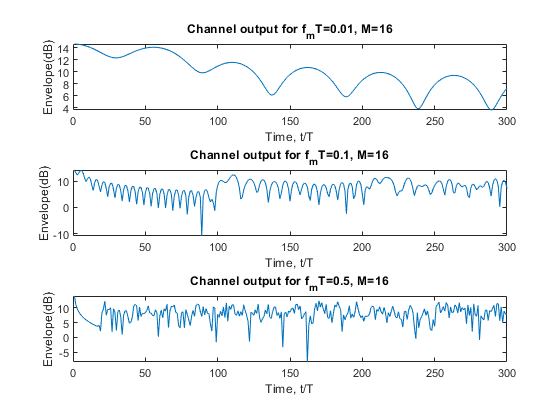


%M=16
% figures of envelope
figure
subplot(3,1,1)
plot(10*log10(env_12(1:300)))
titleStr=sprintf('Channel output for f_mT=%0.2f, M=%d',f_mT(1),M(2));
title(titleStr)
xlabel("Time, t/T")
ylabel('Envelope(dB)')

subplot(3,1,2)
plot(10*log10(env_22(1:300)))
titleStr=sprintf('Channel output for f_mT=%0.1f, M=%d',f_mT(2),M(2));
title(titleStr)
xlabel("Time, t/T")
ylabel('Envelope(dB)')

subplot(3,1,3)
plot(10*log10(env_32(1:300)))
titleStr=sprintf('Channel output for f_mT=%0.1f, M=%d',f_mT(3),M(2));
title(titleStr)
xlabel("Time, t/T")
ylabel('Envelope(dB)')

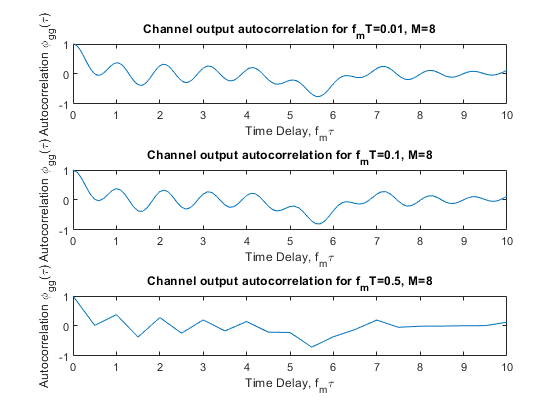


%M=8
%figures of autocorrelation
figure
subplot(3,1,1)
plot([0:f_mT(1):10],Rn_11)
titleStr=sprintf('Channel output autocorrelation for f_mT=%0.2f, M=%d',f_mT(1),M(1));
title(titleStr)
xlabel("Time Delay, f_m\tau")
ylabel('Autocorrelation \phi_{gg}(\tau)')

subplot(3,1,2)
plot([0:f_mT(2):10],Rn_21)
titleStr=sprintf('Channel output autocorrelation for f_mT=%0.1f, M=%d',f_mT(2),M(1));
title(titleStr)
xlabel("Time Delay, f_m\tau")
ylabel('Autocorrelation \phi_{gg}(\tau)')

subplot(3,1,3)
plot([0:f_mT(3):10],Rn_31)
titleStr=sprintf('Channel output autocorrelation for f_mT=%0.1f, M=%d',f_mT(3),M(1));
title(titleStr)
xlabel("Time Delay, f_m\tau")
ylabel('Autocorrelation \phi_{gg}(\tau)')

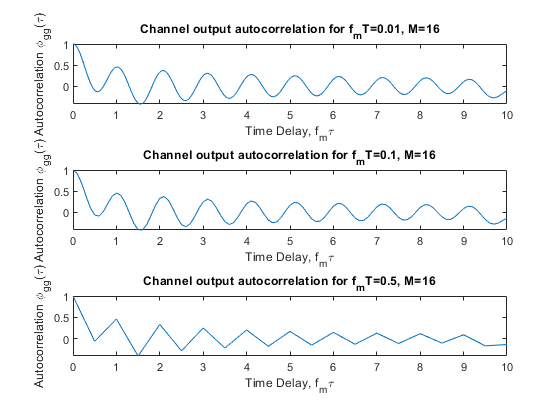




%M=16
%figures of autocorrelation
figure
subplot(3,1,1)
plot([0:f_mT(1):10],Rn_12)
titleStr=sprintf('Channel output autocorrelation for f_mT=%0.2f, M=%d',f_mT(1),M(2));
title(titleStr)
xlabel("Time Delay, f_m\tau")
ylabel('Autocorrelation \phi_{gg}(\tau)')

subplot(3,1,2)
plot([0:f_mT(2):10],Rn_22)
titleStr=sprintf('Channel output autocorrelation for f_mT=%0.1f, M=%d',f_mT(2),M(2));
title(titleStr)
xlabel("Time Delay, f_m\tau")
ylabel('Autocorrelation \phi_{gg}(\tau)')

subplot(3,1,3)
plot([0:f_mT(3):10],Rn_32)
titleStr=sprintf('Channel output autocorrelation for f_mT=%0.1f, M=%d',f_mT(3),M(2));
title(titleStr)
xlabel("Time Delay, f_m\tau")
ylabel('Autocorrelation \phi_{gg}(\tau)')